% Copyright 2022 Oliver Schoen
% Generate LDBA (accepting transitions)
% Here: only deterministic part
clear all; clc;

%% Specify system and regions
% LTI system of the form
% 
% x(t+1) = A x(t) + B u(t) + Bw w(t) 
% 
% y(t) = C x(t) + D u(t)

% Define system parameters
A = 0.9*eye(2);
B = eye(2);
C = eye(2);
D = zeros(2);
Bw = sqrt(0.2)*eye(2);
dim = length(A);

% Specify mean and variance of disturbance w(t) 
mu = zeros(dim, 1); % Mean of disturbance
sigma = eye(dim); % Variance of disturbance

sysLTI = LinModel(A, B, C, D, Bw, mu, sigma);
 
% Bounds on state space 
x1l = -6; % Lowerbound in x1
x1u = 6; % Upperbound in x1
x2l = -6; % Lowerbound in x2
x2u = 6; % Upperbound in x2
sysLTI.X = Polyhedron(combvec([x1l, x1u], [x2l, x2u])');

MOSEK Version 9.3.13 (Build date: 2022-1-24 09:41:28)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86



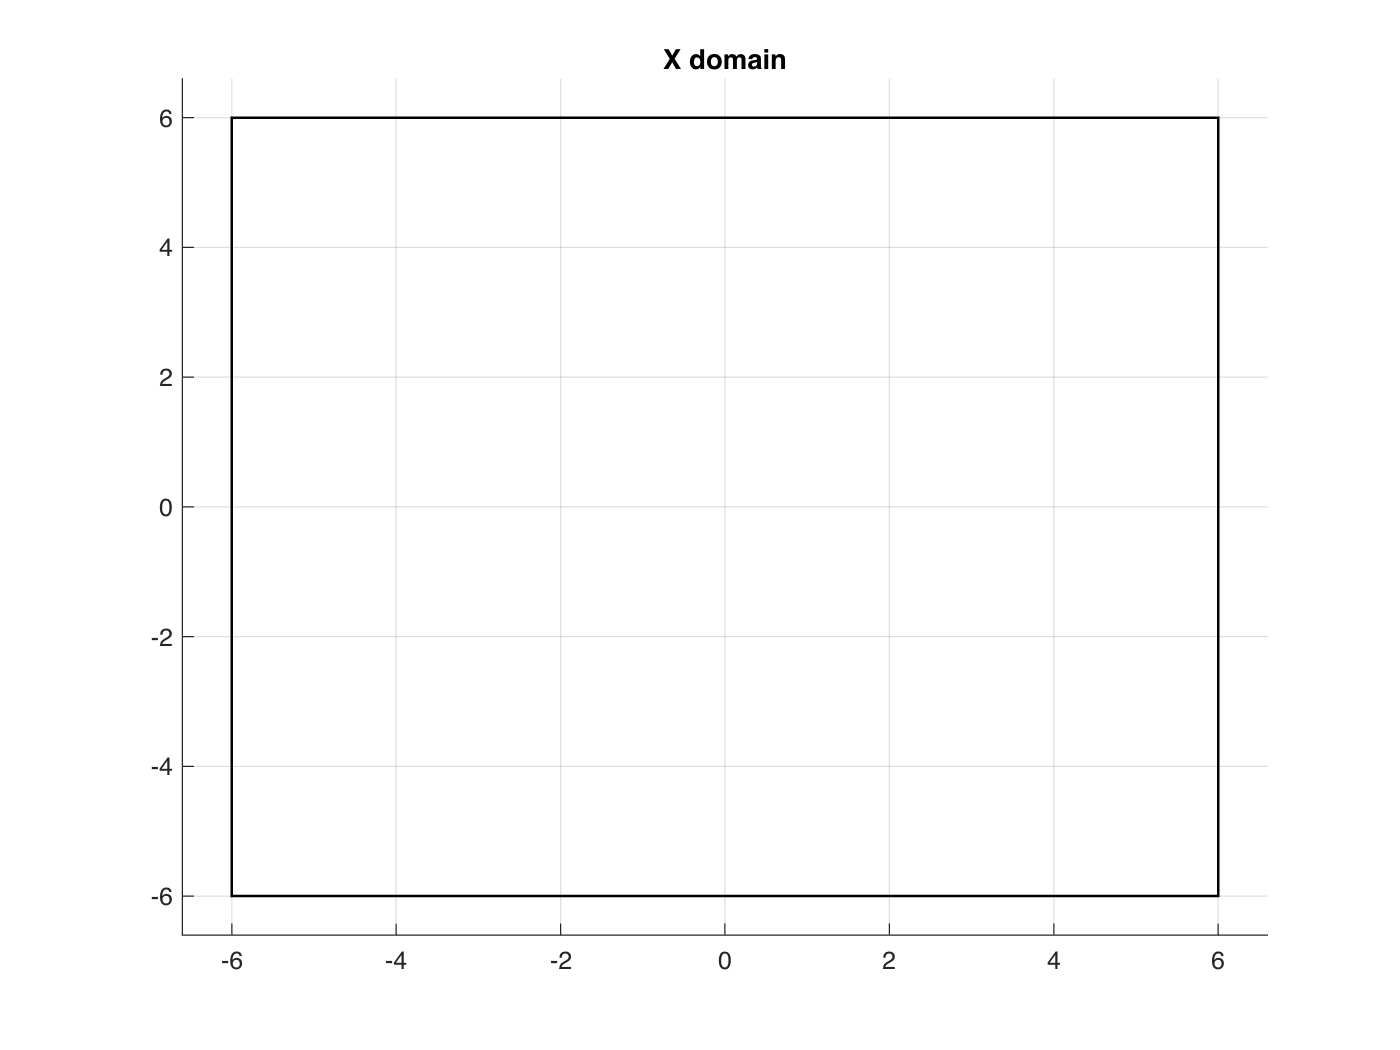

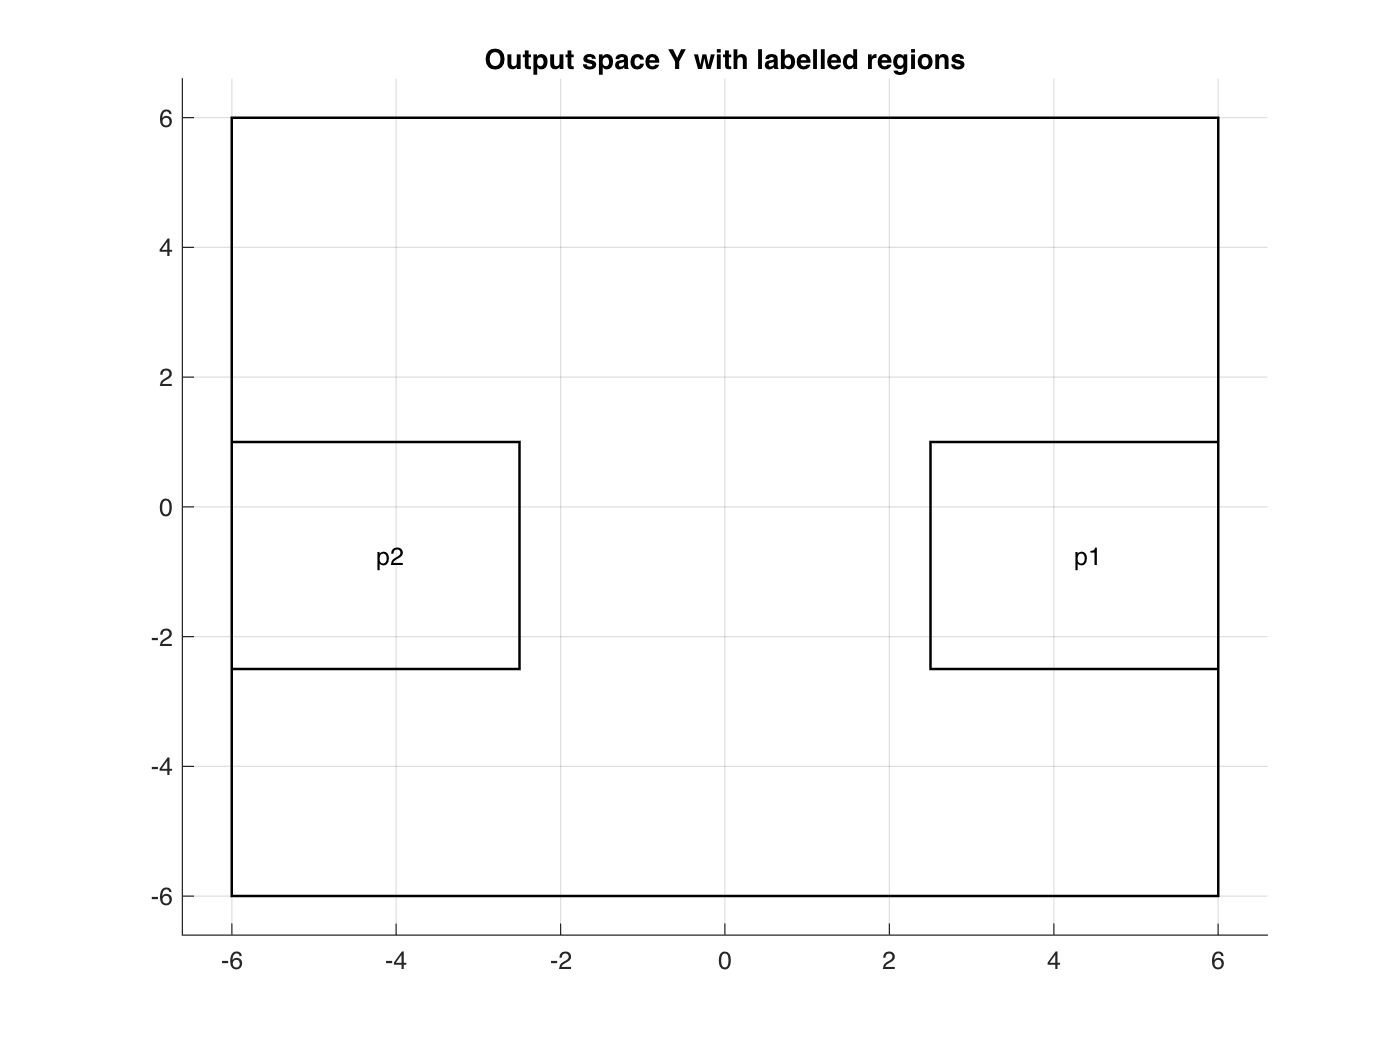


% Bounds on  and input space
ul = [-1; -1]; % Lowerbound input u
uu = [1; 1]; % Upperbound input u
sysLTI.U = Polyhedron(combvec([ul(1), uu(1)], [ul(2), uu(2)])');

% Specify regions for the specification
% Reach region
p1x = [2.5 2.5 6 6 2.5]; % x1-coordinates
p1y = [-2.5 1 1 -2.5 -2.5]; % x2-coordinates
P1 = Polyhedron([p1x; p1y]');

% Avoid region
p2x = -[2.5 2.5 6 6 2.5]; % x1-coordinates
p2y = [-2.5 1 1 -2.5 -2.5]; % x2-coordinates
P2 = Polyhedron([p2x; p2y]');

sysLTI.regions = [P1; P2]; % regions that get specific atomic propositions
sysLTI.AP = {'p1', 'p2'}; % with the corresponding atomic propositions

Plot_sysLTI(sysLTI)

%% Synthesize scLTL formula (or input DFA yourself)
% Reference to compare results
formula_ref = 'G((!p2) U p1)';
DFA_ref = TranslateSpec(formula_ref, sysLTI.AP);

never { /* []((!p2) U p1) */
T0_init:
	if
	:: (p1) -> goto accept_S1
	:: (!p2) -> goto T0_init
	fi;
accept_S1:
	if
	:: (p1) -> goto accept_S1
	:: (!p2) -> goto T0_init
	fi;
}

add state



% % Specify locations
% S = [1 2 3];
% 
% % Specify labels
% act = {' ', 'p3', 'p2', 'p2p3', 'p1', 'p1p3', 'p1p2', 'p1p2p3'};
% 
% % Specify transitions
% trans = [ ...
%     1, 1, 1, 1, 2, 2, 2, 2; ...
%     2, 3, 1, 1, 2, 3, 1, 1; ...
%     3, 3, 1, 1, 3, 3, 1, 1 ...
%     ];

% Specify accepting transitions
% Must be visited infinitely often
% Acc = zeros(length(S), length(act));
% Acc(2, 2) = deal(1);
% Acc(2, 6) = deal(1);

% LDBA = struct( ...
%     'S', S, ...
%     'S0', 1, ...
%     'Acc', Acc, ... % Accepting transitions
%     'act', {act}, ...
%     'trans', trans, ...
%     'sink', find([0, 0]) ... % Empty double row vector
%     );

% % Easy example
% LDBA = struct( ...
%     'S', [1], ...
%     'S0', 1, ...
%     'Acc', [0, 1], ... % Accepting transitions
%     'act', {DFA_ref.act}, ...
%     'trans', [1, 1], ...
%     'sink', find([0, 0]) ... % Empty double row vector
%     );
% Easy example with avoid p2
LDBA = struct( ...
    'S', [1, 2], ...
    'S0', 1, ...
    'Acc', [0, 0, 1, 1; 0, 0, 0, 0], ... % Accepting transitions
    'act', {DFA_ref.act}, ...
    'trans', [1, 2, 1, 1; 2, 2, 2, 2], ...
    'sink', find([0, 0]) ... % Empty double row vector
    );

%% Construct abstract model by gridding it

disp('Start gridding...');

Start gridding...


tGridStart = tic;

% Specify division of input space for actuation and feedback
ula = ul; % Part of input space for actuation (lowerbound)
uua = uu;
ulf = ul - ula; % Part of input space for feedback (lowerbound)
uuf = uu - uua;

% Specify granularity of abstraction/gridding
lu = 3; % Division of input space
lx1 = 110; % Division of state space in x1-direction
lx2 = 110;% Division of state space in x2-direction

uhat = combvec(linspace(ula(1), uua(1), lu), linspace(ula(2), uua(2), lu));

l = [lx1, lx2]; % Number of grid cells in x1- and x2-direction
tol = 10^(-6);
sysAbs = Gridding(sysLTI, uhat, l, tol, 'TensorComputation', true);

% Save some extra system parameters into struct
sysAbs.orig = sysLTI;

% Label output space
regions = {p1x, p1y; p2x, p2y};
sysAbs = labelos(sysAbs, LDBA, regions, sysLTI.AP);

tGridEnd = toc(tGridStart);
disp(['---> finished gridding in ', num2str(tGridEnd), ' seconds'])

---> finished gridding in 0.17015 seconds


%% Compute delta based on epsilon

% Pick epsilon
[epsilonBounds] = ComputeEpsilonBounds(sysLTI, sysLTI.mu, sysLTI.sigma, sysAbs.beta);
epsilon = max(epsilonBounds); %1.3;
 
disp('Starting to compute delta for chosen epsilon...');

Starting to compute delta for chosen epsilon...


tSimStart = tic;

% Calculate delta based on chosen epsilon
[delta, D_m, K] = ComputeDelta(epsilon, sysLTI, sysLTI.mu, sysLTI.sigma, sysAbs.beta);
if delta > 1e-3
    warning("The value of delta is greater than %g. The value function is unlikely to converge to a value greater zero.", delta)
end

% Calculate simulation relation
rel = SimRel(epsilon, delta, D_m);

tSimEnd = toc(tSimStart);

disp(['delta = ', num2str(delta), ', epsilon = ', num2str(epsilon) ])

delta = 0, epsilon = 1.5429


disp(['---> finished computing eps delta in ', num2str(tSimEnd), ' seconds'] )

---> finished computing eps delta in 6.9122 seconds


%% Synthesize controller
disp('Starting to compute robust controller...')

Starting to compute robust controller...


rel.NonDetLabels = NonDeterministicLabelling(sysAbs.outputs, sysLTI.regions, rel);

N = 100;     % time horizon

xi = 0.999; % Probability of NOT jumping to phi every time travelling an accepting transition
augProdGMDP = genAugProdGMDP(sysAbs, LDBA, xi);

satProp = SynthesizeRobustControllerAugmented(augProdGMDP, rel, N*500, false);

Start computing robust policy...
Elapsed time is 0.019304 seconds.
Value iteration has converged.
Number of iterations required, k = 28375


satProp_ref = SynthesizeRobustController(sysAbs, DFA_ref, rel, N, false);

 <---- Start computing robust policy 
Elapsed time is 0.003582 seconds.
Convergence reached!
Number of iteration required, k=71
Elapsed time is 0.106124 seconds.
 ----> Finished computing robust policy in 0.11125


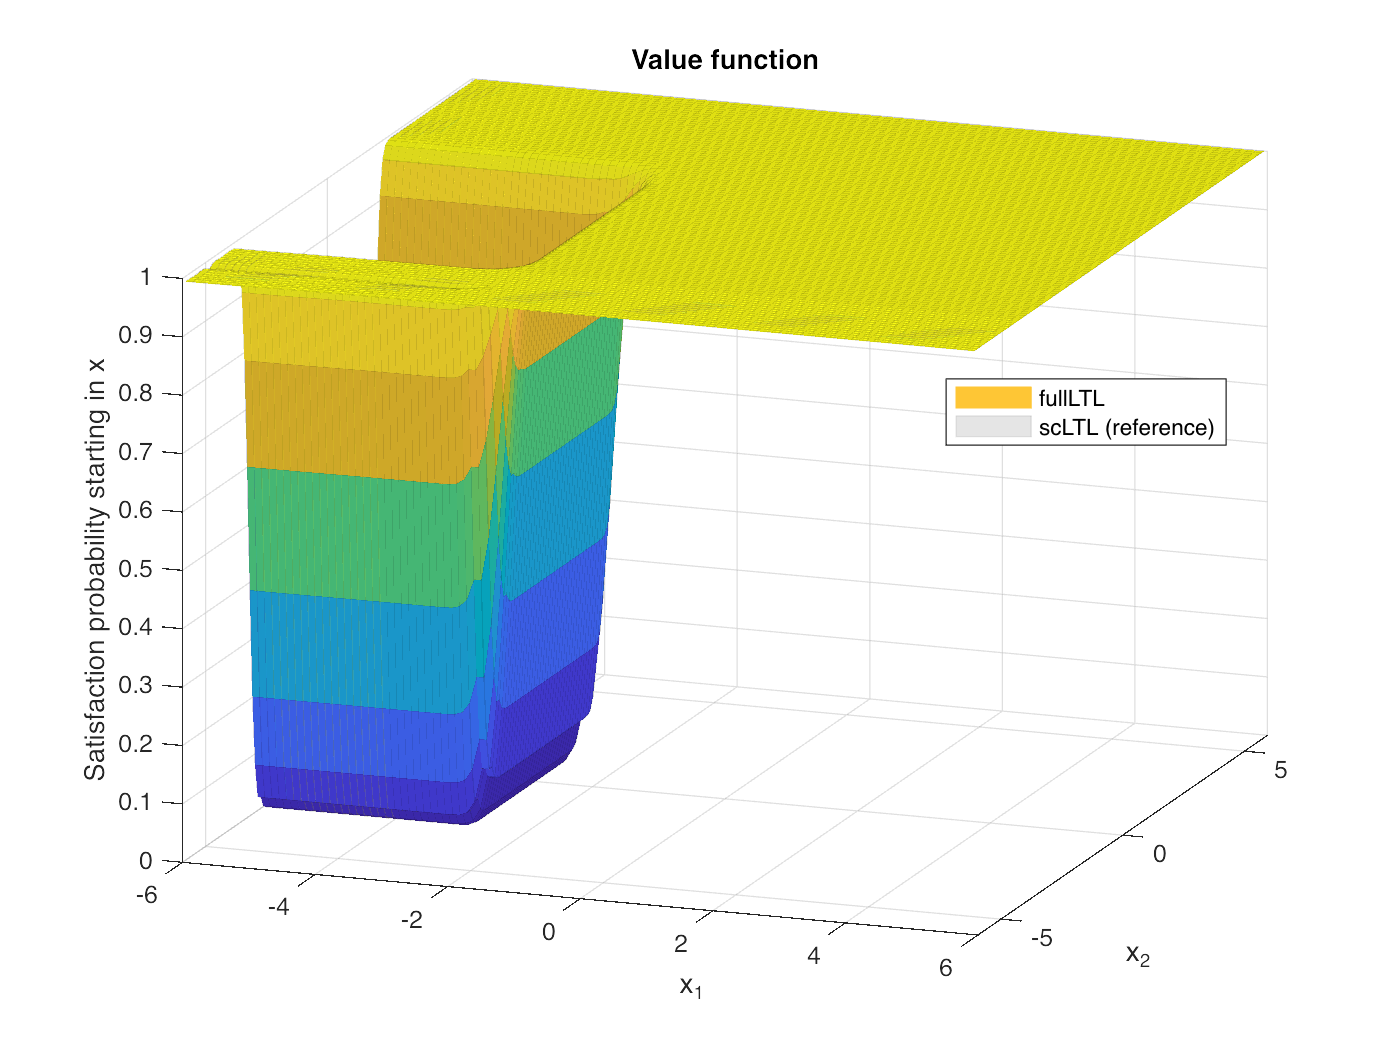

figure
[X1hat, X2hat] = ndgrid(sysAbs.hx{1}, sysAbs.hx{2});
sref = surf(X1hat, X2hat, reshape(satProp_ref(DFA_ref.S0, :), lx1, lx2), ...
    'EdgeColor', 'k', 'EdgeAlpha', .1, ...
    'FaceColor', 'k', 'FaceAlpha', .1, ...
    'DisplayName', 'scLTL (reference)');
hold on
s = surf(X1hat, X2hat, reshape(satProp(LDBA.S0, :), lx1, lx2), ...
    'EdgeColor', 'interp', 'EdgeAlpha', .1, ...
    'FaceAlpha', 1, ...
    'DisplayName', 'fullLTL');
hold off
zlim([0, 1])
view(20, 20)
xlabel("x_1")
ylabel("x_2")
zlabel("Satisfaction probability starting in x")
title("Value function")
legend([s, sref], 'Location', 'best')